clc
clearvars

method = 'sgdm'; %sgdm adam rmsprop
initLearnRate = 0.1;
MaxEpochs = 100 ;
MiniBatchSize  = 64;
Momentum = 0.7;

% Load CIFAR-10 data from MATLAB dataset
dataDir = 'cifar-10-batches-mat';

% Load training data
trainImages = [];
trainLabels = [];
for i = 1:4
    batchFile = fullfile(dataDir, ['data_batch_' num2str(i) '.mat']);
    batch = load(batchFile);
    trainImages = cat(4, trainImages, reshape(batch.data',32,32,3,[]));
    trainLabels = [trainLabels; batch.labels];
end

valBatch = load(fullfile(dataDir, 'data_batch_5.mat'));
valImages = reshape(valBatch.data',32,32,3,[]);
valLabels = valBatch.labels';

% Load test data
testBatch = load(fullfile(dataDir, 'test_batch.mat'));
testImages = reshape(testBatch.data',32,32,3,[]);
testLabels = testBatch.labels';

% Convert to categorical labels
trainLabels = categorical(trainLabels);
valLabels   = categorical(valLabels);
testLabels  = categorical(testLabels);

% Permute because CIFAR stores as (row, col, channel)
trainImages = permute(trainImages,[2 1 3 4]);
valImages   = permute(valImages,[2 1 3 4]);
testImages  = permute(testImages,[2 1 3 4]);

imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-10,10], ...
    'RandXTranslation',[-3 3], ...
    'RandYTranslation',[-3 3], ...
    'RandXReflection',true);

% Convert to datastore (better for training)
trainDS = augmentedImageDatastore([32 32 3], trainImages, trainLabels, ...
    'DataAugmentation', imageAugmenter);
valDS = augmentedImageDatastore([32 32 3], valImages, valLabels);
testDS  = augmentedImageDatastore([32 32 3], testImages, testLabels);


layers = [
    imageInputLayer([32 32 3])

1st conv layer

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

2nd conv layer

    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2) 

3rd conv layer

    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2) 

4th conv layer

    % convolution2dLayer(3,256,'Padding','same')
    % batchNormalizationLayer
    % reluLayer
    % convolution2dLayer(3,256,'Padding','same')
    % batchNormalizationLayer
    % reluLayer
    % 
    

Classifier

    globalAveragePooling2dLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
];


global trainingInfo
trainingInfo = struct('TrainAcc', [], 'ValAcc', [], 'TrainLoss', [], 'ValLoss', []);

options = trainingOptions(method, ...
    'InitialLearnRate',initLearnRate, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',2, ...           
    'LearnRateDropFactor',0.1, ...          
    'MaxEpochs',MaxEpochs, ...
    'MiniBatchSize',MiniBatchSize, ...
    'Shuffle','every-epoch', ...
    'L2Regularization',0.001, ...
    'ValidationData',valDS, ...
    'ValidationFrequency',50, ...
    'ValidationPatience',25,...
    'Verbose',false, ...
    'Plots','training-progress',...
    'Momentum',Momentum,...
    OutputFcn=@(info) recordMetrics(info));
    
    

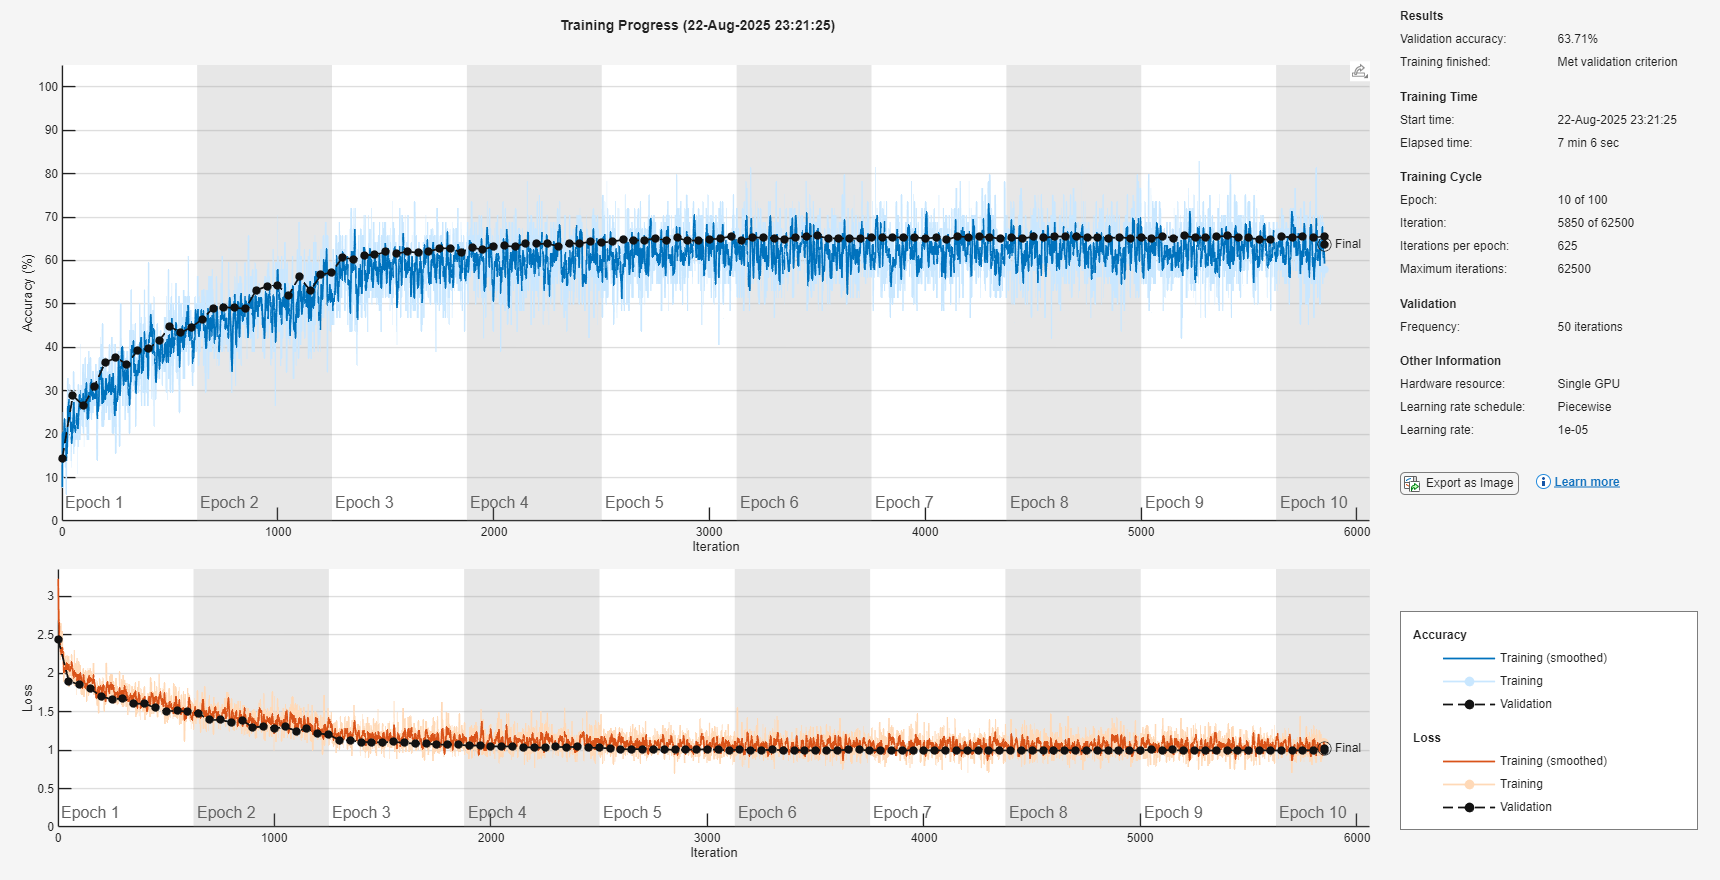

net = trainNetwork(trainDS, layers, options);

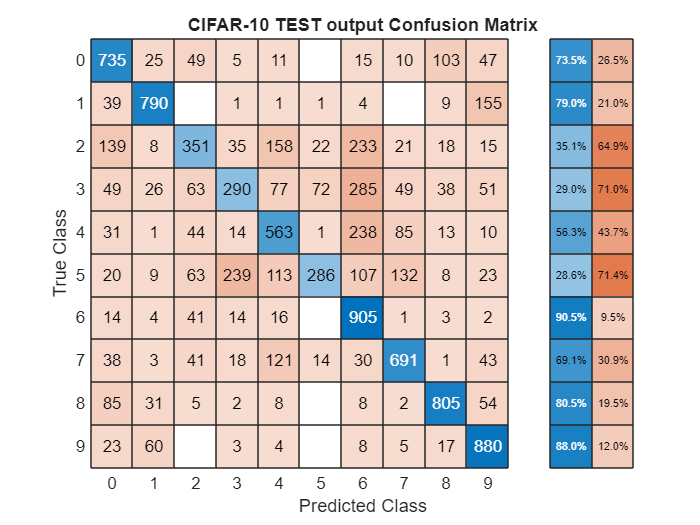

% Create confusion matrix
figure;
YPred = classify(net, testDS);
cm = confusionchart(testLabels, YPred);
cm.Title = 'CIFAR-10 TEST output Confusion Matrix';
cm.RowSummary = 'row-normalized'; % shows per-class accuracy in %

cmMatrix = cm.NormalizedValues;  % row-normalized values (0-1)
numPerClass = sum(cmMatrix,2);        % for normalized it's 1 per row, skip
overallAcc = sum(diag(cmMatrix));    % average of diagonal = average per-class accuracy
acc = num2str(overallAcc*(100/10000));


baseFilename = sprintf('CIFAR10_%s_LR%.0e_BS%d_M%.0e_E%d_ACC%.2f', ...
                       method,...
                       options.InitialLearnRate, ...
                       options.MiniBatchSize, ...
                       options.Momentum,...
                       options.MaxEpochs,...
                       overallAcc/100);
 %options.Momentum,...


outputFolder = fullfile('Test Output', baseFilename);
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end
save(fullfile(outputFolder, [baseFilename '.mat']), 'net');

saveas(gcf, fullfile(outputFolder, [baseFilename '_CM.png']));

disp(['Overall Accuracy (from CM): ' acc '%']);

Overall Accuracy (from CM): 62.96%


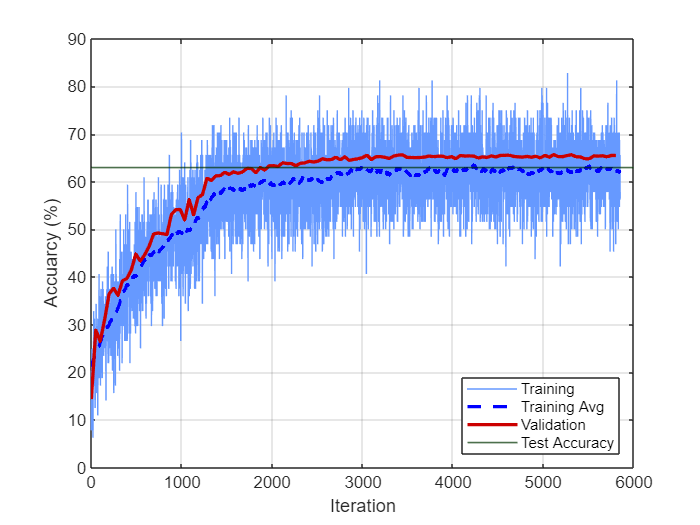

numIterationsPerEpoch = length(trainingInfo.TrainLoss) / length(trainingInfo.ValLoss);
 figure;
    plot(1:length(trainingInfo.TrainAcc), trainingInfo.TrainAcc, 'Color', [0.4 0.6 1], 'LineWidth', 0.1); 
    hold on;
    
    avgTrainAcc = movmean(trainingInfo.TrainAcc, 150);  
    plot(1:length(avgTrainAcc), avgTrainAcc,'--', 'Color', [0 0 1], 'LineWidth', 2);

    plot(1:numIterationsPerEpoch:length(trainingInfo.TrainLoss), trainingInfo.ValAcc,'Color', [0.8 0 0], 'LineWidth', 2);
    yline(overallAcc/100, '-', 'Color', [0 0.2 0], 'LineWidth', 1);
    grid();
    xlabel('Iteration'); ylabel('Accuarcy (%)');
    legend('Training','Training Avg','Validation','Test Accuracy', 'Location', 'southeast');
    saveas(gcf, fullfile(outputFolder, [baseFilename '_AccuarcyCurves.png']));
hold off;

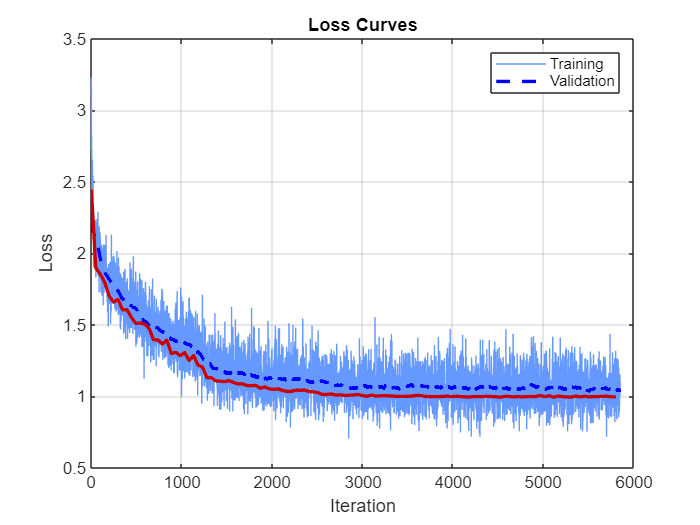

figure;
    plot(1:length(trainingInfo.TrainLoss), trainingInfo.TrainLoss, 'Color', [0.4 0.6 1],'LineWidth',0.1); hold on;
    
    avgTrainloss = movmean(trainingInfo.TrainLoss, 150);  
    plot(1:length(avgTrainloss), avgTrainloss,'--', 'Color', [0 0 1], 'LineWidth', 2);

    plot(1:numIterationsPerEpoch:length(trainingInfo.TrainLoss), trainingInfo.ValLoss,'Color',[0.8 0 0],'LineWidth',2);
    xlabel('Iteration'); ylabel('Loss');
    grid();
    legend('Training','Validation'); title('Loss Curves');
    saveas(gcf, fullfile(outputFolder, [baseFilename '_LossCurves.png']));

layerFile = fullfile(outputFolder, [baseFilename '_Layers.csv']);
fid = fopen(layerFile, 'w');

% Write header
fprintf(fid, 'Index,LayerType,OutputSize,NumLearnableParams\n');

for i = 1:length(layers)
    layerInfo = layers(i);
    
    % Layer type
    typeStr = class(layerInfo);
    
    % Output size
    if isprop(layerInfo,'OutputSize')
        outSize = mat2str(layerInfo.OutputSize);
    else
        outSize = '';
    end
    
    % Number of learnable parameters
    if isprop(layerInfo,'NumLearnableParameters')
        numParams = layerInfo.NumLearnableParameters;
    else
        numParams = 0;
    end
    
    fprintf(fid, '%d,%s,%s,%d\n', i, typeStr, outSize, numParams);
end

fclose(fid);

function stop = recordMetrics(info)
    global trainingInfo 
    stop = false;
    if ~isempty(info.TrainingAccuracy)
        trainingInfo.TrainAcc(end+1) = info.TrainingAccuracy;
        trainingInfo.TrainLoss(end+1) = info.TrainingLoss;
    end
    if isfield(info,'ValidationAccuracy') && ~isempty(info.ValidationAccuracy)
        trainingInfo.ValAcc(end+1) = info.ValidationAccuracy;
        trainingInfo.ValLoss(end+1) = info.ValidationLoss;
    end
end